s = tf("s")

s =
 
  s
 
Continuous-time transfer function.



G = 2*(s+1)/(s^2+3*s+4)

G =
 
     2 s + 2
  -------------
  s^2 + 3 s + 4
 
Continuous-time transfer function.



p = [-2, -3];
z = -1;
K = 2;

G1 = zpk(z,p,K)

G1 =
 
    2 (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



ans =     -2
    -3


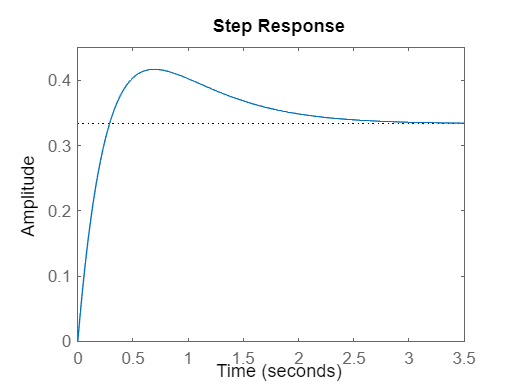

step(G1)

% ex 
K2 = 0.2;
p2 = ((s^2+s+1)*(s+0.2));
G2 = K2 / pol

G2 =
 
              0.2
  ---------------------------
  s^3 + 1.2 s^2 + 1.2 s + 0.2
 
Continuous-time transfer function.



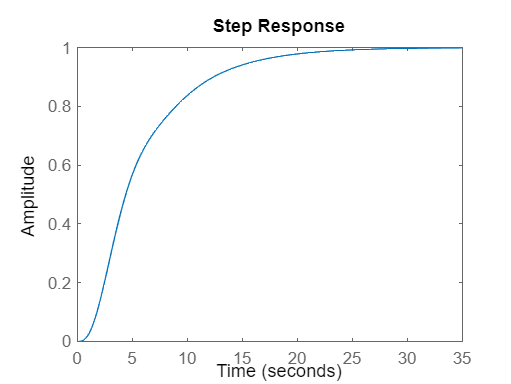

step(G2)

% 3.5 A
Kp = 5;
G2f = feedback(Kp * G2, 1)

G2f =
 
               1
  ---------------------------
  s^3 + 1.2 s^2 + 1.2 s + 1.2
 
Continuous-time transfer function.



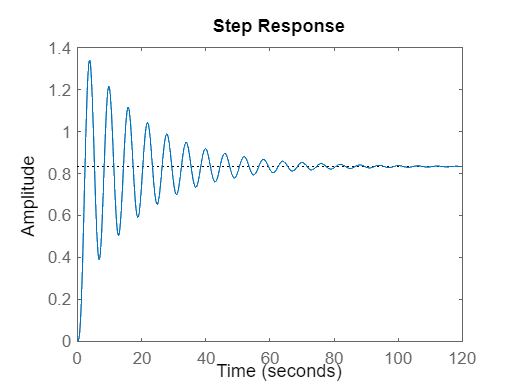


step(G2f)

% 3.5 B
Kp = 1;
Ki = 1;
F = (Kp*s+Ki)/s

F =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



G2f2 = feedback(F * G2, 1)

G2f2 =
 
               0.2 s + 0.2
  -------------------------------------
  s^4 + 1.2 s^3 + 1.2 s^2 + 0.4 s + 0.2
 
Continuous-time transfer function.



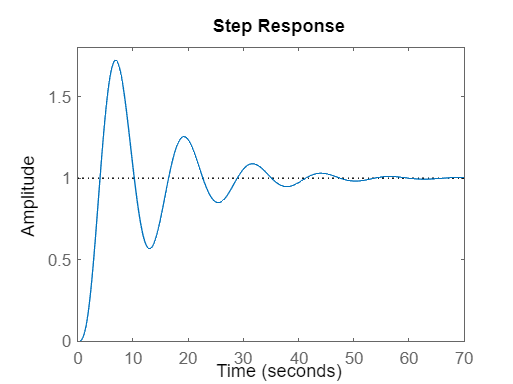

step(G2f2)

% 3.5 c
Kp = 1

Kp = 1

Ki = 1

Ki = 1

Kd = 3

Kd = 3

T = 0.1

T = 0.1000


F = Kp +Ki/s + Kd*s / (s*T+1)

F =
 
  3.1 s^2 + 1.1 s + 1
  -------------------
      0.1 s^2 + s
 
Continuous-time transfer function.



G2f3 = feedback(F * G2, 1)

G2f3 =
 
                  0.62 s^2 + 0.22 s + 0.2
  -------------------------------------------------------
  0.1 s^5 + 1.12 s^4 + 1.32 s^3 + 1.84 s^2 + 0.42 s + 0.2
 
Continuous-time transfer function.



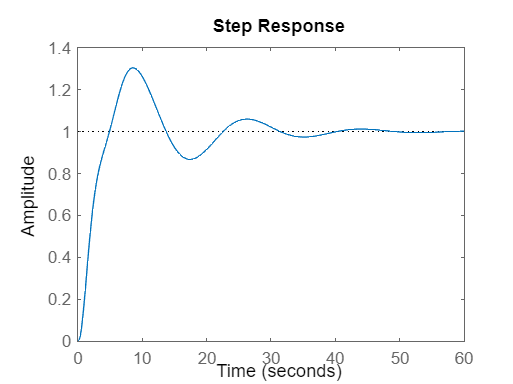

step(G2f3)

% 2.6
Ga = 1/(s^2+2*s+1)

Ga =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



Gb = 1/(s^2+0.4*s+1)

Gb =
 
         1
  ---------------
  s^2 + 0.4 s + 1
 
Continuous-time transfer function.



Gc = 1/(s^2+5*s+1)

Gc =
 
        1
  -------------
  s^2 + 5 s + 1
 
Continuous-time transfer function.



Gd = 1/(s^2+s+1)

Gd =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



Ge = 4/(s^2+2*s+4)

Ge =
 
        4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.



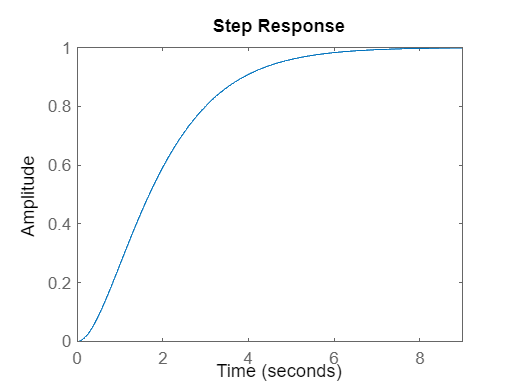

step(Ga)

pole(Ga)

ans =     -1
    -1


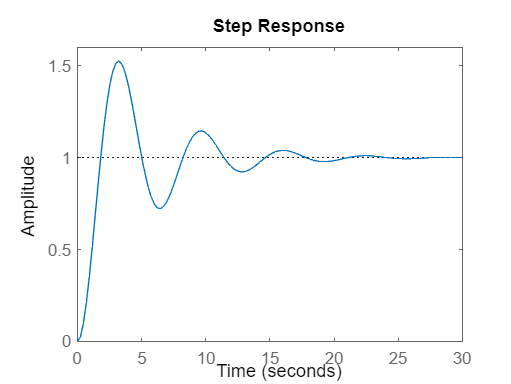

step(Gb)

pole(Gb)

ans =   -0.2000 + 0.9798i
  -0.2000 - 0.9798i


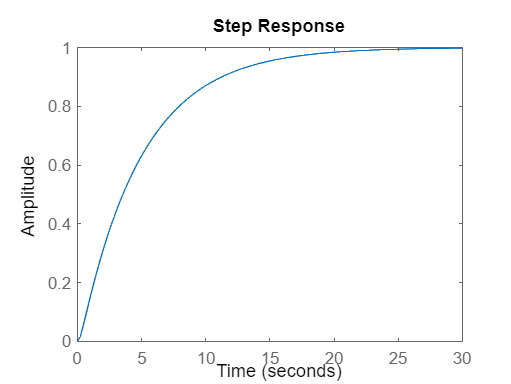

step(Gc)

pole(Gc)

ans =    -4.7913
   -0.2087


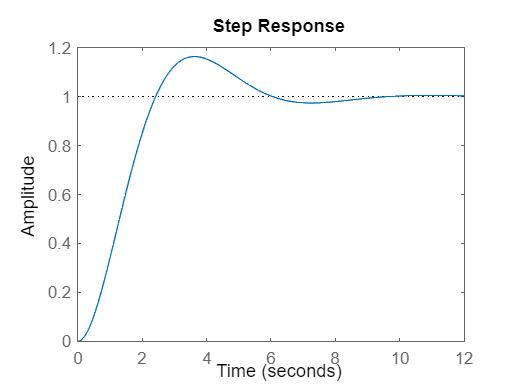

step(Gd)

pole(Gd)

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


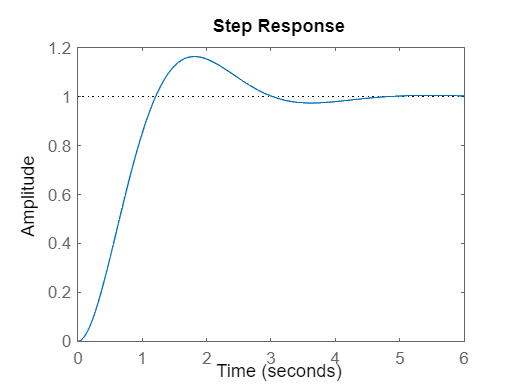

step(Ge)

pole(Ge)

ans =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i


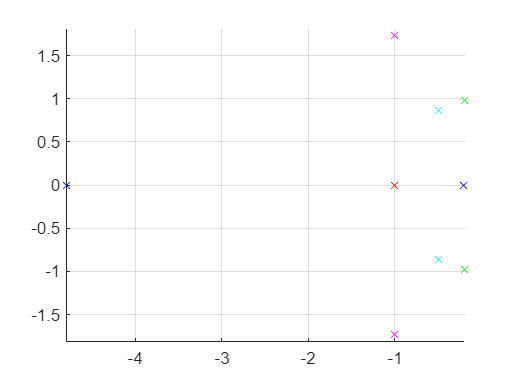

clf
hold on
grid on
axis on
axis equal

plot(real(pole(Ga)), imag(pole(Ga)), 'xr')
plot(real(pole(Gb)), imag(pole(Gb)), 'xg')
plot(real(pole(Gc)), imag(pole(Gc)), 'xb')
plot(real(pole(Gd)), imag(pole(Gd)), 'xc')
plot(real(pole(Ge)), imag(pole(Ge)), 'xm')



% higher im than re -> more oscillation
% pos pol no stable

% 2.7
clf
a = -10

a = -10

G27 = (a*s+1)/(s^2+2*s+1)

G27 =
 
    -10 s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



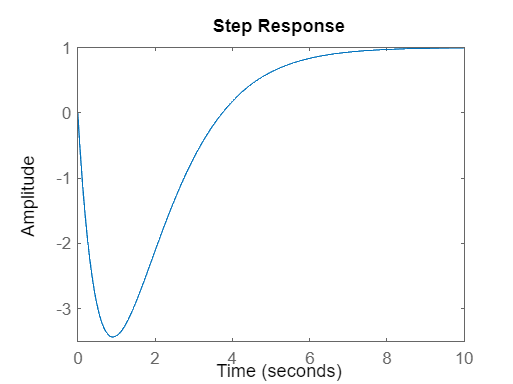

step(G27)

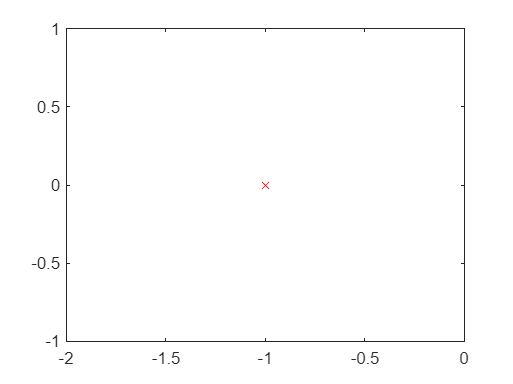

plot(real(pole(G27)), imag(pole(G27)), 'xr')